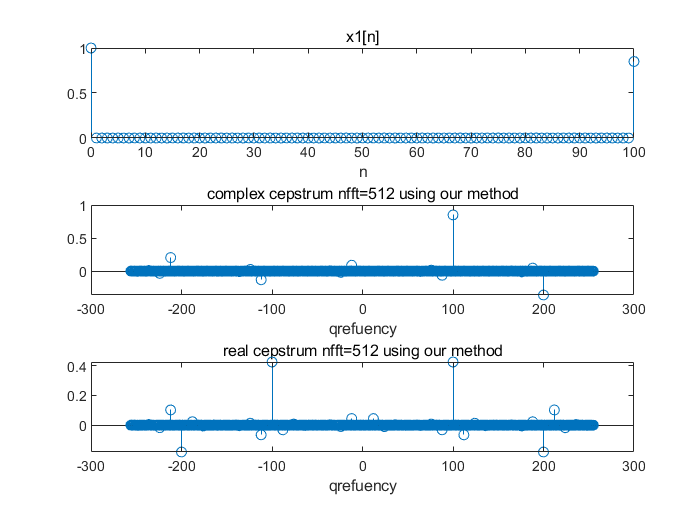

x=[1 zeros(1,99) 0.85];
nfft=512;
[ccepstrum,rcepstrum]=Cepstrum(x,nfft);
subplot(3,1,1);
stem(0:100,x);
title('x1[n]');
xlabel('n');
subplot(3,1,2);
stem(-nfft/2:1:nfft/2-1,ccepstrum);
title('complex cepstrum nfft=512 using our method');
xlabel('qrefuency')
subplot(3,1,3);
stem(-nfft/2:1:nfft/2-1,rcepstrum);
title('real cepstrum nfft=512 using our method');
xlabel('qrefuency')

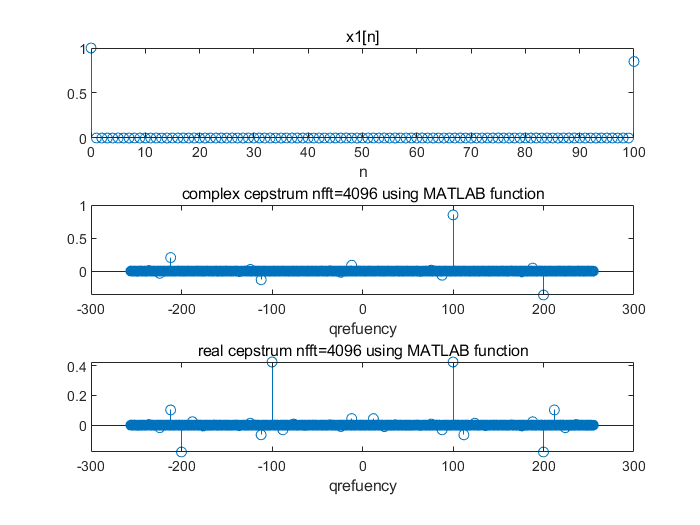


xhat=ifftshift(cceps(x,nfft));
x_new=[x zeros(1,nfft-length(x))];
[y,ym]=rceps(x_new);
figure
subplot(3,1,1);
stem(0:100,x);
title('x1[n]');
xlabel('n');
subplot(3,1,2);
stem(-nfft/2:1:nfft/2-1,xhat);
title('complex cepstrum nfft=4096 using MATLAB function');
xlabel('qrefuency')
subplot(3,1,3);
stem(-nfft/2:1:nfft/2-1,ifftshift(y));
title('real cepstrum nfft=4096 using MATLAB function');
xlabel('qrefuency')